`WARNASOORIYA W.A.V.G. | E/17/372 | EE599 AUDIO ENGINEERING AND ACOUSTICS`

## Pitch Estimation using FFT method

### Methodology 

- Input Audio Signal: You start with an input audio signal. This signal is a wave that represents sound, like music or speech.

- Dividing into Time Segments: To analyze the signal, you first break it into small segments over time. These segments are like snapshots of the audio at different moments.

- Frequency Domain: Each of these segments is then transformed into the frequency domain using the FFT. This transformation tells us which frequencies are present in that segment.

- Magnitude Information: The FFT gives us information about how much of each frequency is present. We get a magnitude value for each frequency component.

- Frequency Bins: The FFT divides the frequency range into bins. Each bin represents a specific range of frequencies. The magnitude value tells us how much energy there is in each bin.

- Peak Frequency: We often look for the bin with the highest magnitude. This represents the dominant frequency in that segment.

- Time vs. Frequency: By repeating this process for each time segment, we can create a map that shows how the dominant frequency changes over time. This map is called a spectrogram.

- Pitch Estimation: The dominant frequency at a given time is often related to the pitch of the sound at that moment. So, by finding the dominant frequency over time, we can estimate the pitch variation in the audio.

### Pitch Estimation for The Given Sample Audio

filename = "D:\ACADEMIC E17 DEEE UOP\Sem_8_UOP\EE599 AUDIO ENGINEERING AND ACOUSTICS (TE)(3)\ACTIVITIES\ACTIVITY 1\Dataset\sarigamapa.wav";
[audio, sampleRate] = audioread(filename);
% Converting the audio file to mono if stereo 
if size(audio, 2) == 2
    audio = mean(y, 2);   
end

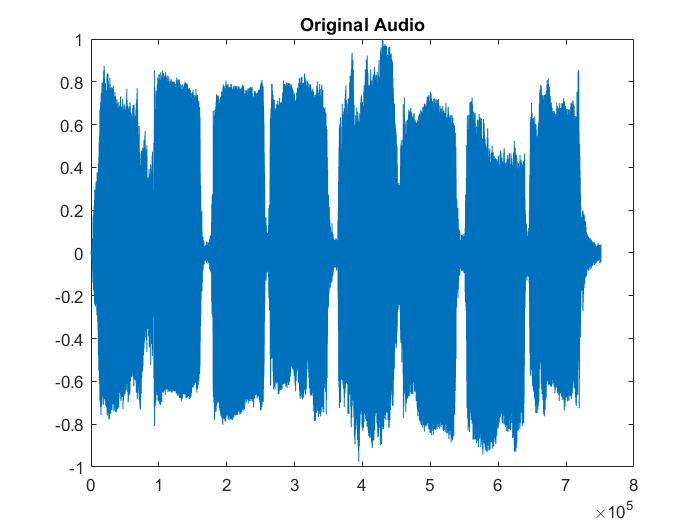

% Create plot of audio
h1 = plot(audio,'DisplayName','audio');

% Add ylabel, title, and legend
ylabel('audio')
title('audio')
legend
legend('off');
title('Original Audio');
ylabel('');
ylim([-1 1]);

#### Pitch estimation for a sliced audio sample

audio_sliced = audio(sampleRate*0.4:sampleRate*1.5);

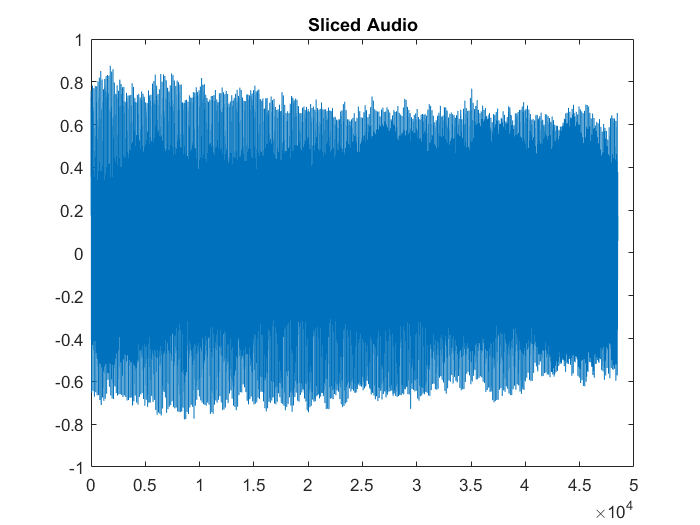

% Create plot of audio_sliced
h2 = plot(audio_sliced,'DisplayName','audio_sliced');

% Add ylabel, title, and legend
ylabel('audio_sliced')
title('audio_sliced')
legend
legend('off'); 
title('Sliced Audio'); 
ylabel(''); 
ylim([-1 1]);


% Defining time vector
t = (0:length(audio_sliced)-1) / sampleRate;
% Taking the FFT of sliced audio
fft_audio_sliced = fft(audio_sliced);                      
% Calculate the magnitude of the FFT    
mag_fft_audio_sliced = abs(fft_audio_sliced);
% Create a frequency vector
f = (0:length(fft_audio_sliced)-1) * sampleRate / length(fft_audio_sliced);
% Find the index of the maximum magnitude in the FFT
[max_mag_sliced, max_index_sliced] = max(mag_fft_audio_sliced);
% Calculate the corresponding frequency (pitch) in Hertz
pitch_Hz_sliced = f(max_index_sliced)

pitch_Hz_sliced = 350.9019

#### Pitch estimation against time for the given Sample Audio

time_vec = (0:length(audio)-1) / sampleRate;

pitch_values = zeros(1, length(audio));
time_values = zeros(1, length(audio));

window_size_sec = 0.02;

for i = 1:length(audio) - round(window_size_sec*sampleRate)
    window = audio(i:i+round(window_size_sec*sampleRate));
    fft_audio = fft(window);
    mag_fft_audio = abs(fft_audio);
    freq_vec = (0:length(fft_audio)-1) * sampleRate / length(fft_audio);
    [max_mag, max_index] = max(mag_fft_audio);
    pitch_Hz = freq_vec(max_index);
    pitch_values(i) = pitch_Hz;
    time_values(i) = time_vec(i);
end


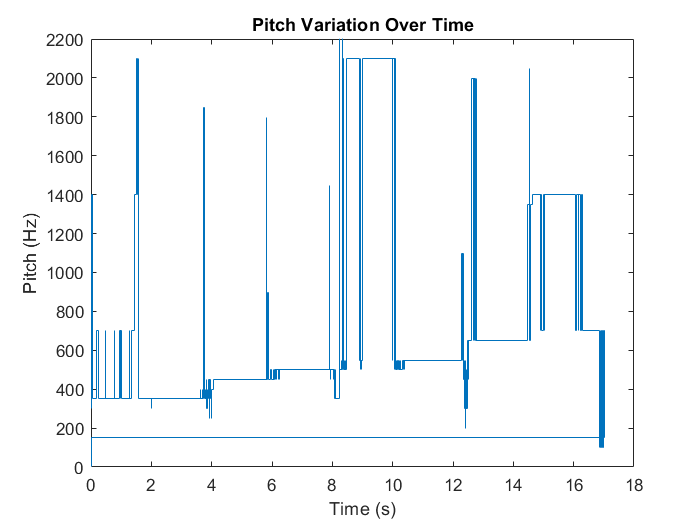

% Create stairs of time_values and pitch_values
h3 = stairs(time_values,pitch_values,'DisplayName','pitch_values');

% Add xlabel, ylabel, title, and legend
xlabel('time_values')
ylabel('pitch_values')
title('time_values vs. pitch_values')
legend
title('Pitch Variation Over Time'); 
ylim([0 2200]); 
xlabel('Time (s)'); 
ylabel('Pitch (Hz)'); 
legend('off');

### Pitch Estimation for a Selected Song

filename = "D:\ACADEMIC E17 DEEE UOP\Sem_8_UOP\EE599 AUDIO ENGINEERING AND ACOUSTICS (TE)(3)\ACTIVITIES\ACTIVITY 1\Dataset\Laa Sanda Aaye.mp3";
[audio, sampleRate] = audioread(filename);

if size(audio, 2) == 2
    audio = mean(audio, 2);   
end

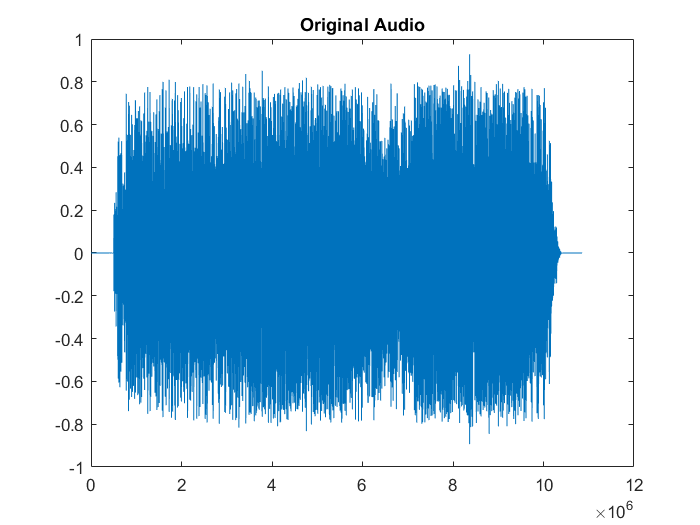

% Create plot of audio
h1 = plot(audio,'DisplayName','audio');

% Add ylabel, title, and legend
ylabel('audio')
title('audio')
legend
legend('off');
title('Original Audio');
ylabel('');
ylim([-1 1]);

time_vec = (0:length(audio)-1) / sampleRate;

pitch_values = zeros(1, length(audio));
time_values = zeros(1, length(audio));

window_size_sec = 0.02;

for i = 1:length(audio) - round(window_size_sec*sampleRate)
    window = audio(i:i+round(window_size_sec*sampleRate)); 
    fft_audio = fft(window);
    mag_fft_audio = abs(fft_audio);
    freq_vec = (0:length(fft_audio)-1) * sampleRate / length(fft_audio);
    [max_mag, max_index] = max(mag_fft_audio);
    pitch_Hz = freq_vec(max_index);
    pitch_values(i) = pitch_Hz;
    time_values(i) = time_vec(i);
end


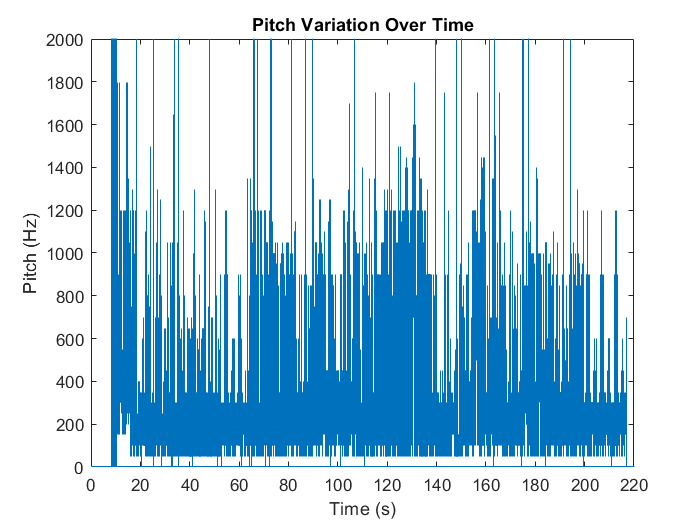

% Create stairs of time_values and pitch_values
h5 = stairs(time_values,pitch_values,'DisplayName','pitch_values');

% Add xlabel, ylabel, title, and legend
xlabel('time_values')
ylabel('pitch_values')
title('time_values vs. pitch_values')
legend
title('Pitch Variation Over Time');
xlabel('Time (s)');
ylabel('Pitch (Hz)');
legend('off');
ylim([0 2000]);
xlim([0 220]);